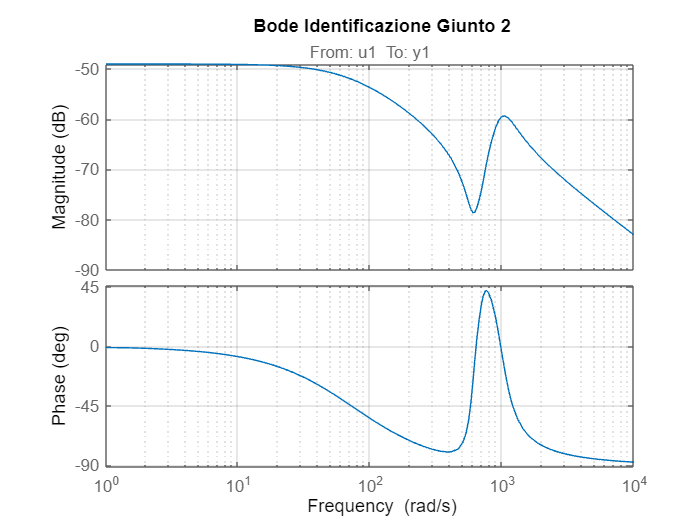

clear all
close all
clc
load ide_modelli_scara.mat

G2 = modello_continuo_q2;
figure
bode(G2)
grid on
title('Bode Identificazione Giunto 2')

tramite la funzione damp vediamo dove si trovano i poli e gli zeri del sistema identificato per trovare le frequenze di risonnza e antirisoanza per togliere il picco introdotto dalla risonanza

dataG2=damp(G2)

dataG2 =    73.6222
  712.8826
  712.8826
  986.8044
  986.8044


Di seguito viene progettato il filtro notch elimina banda con una frequenza  pari a 986.8 rad/s. 

Poi per tentativi, sono stati decisi i valori ottimali di xci_z e xci_p che indicano la selettività del filtro notch

Wn_notch2 = 986.8;
xci_z2=0.2; %aggiustate xci_z e xci_p per rendere il filtro più o meno selettivo
xci_p2=0.7;
s=tf('s');
notch=(s^2+2*xci_z2*Wn_notch2*s+Wn_notch2^2)/(s^2+2*xci_p2*Wn_notch2*s+Wn_notch2^2);

Verifica del filtro mediante l'utilizzo dei diagrammi di bode

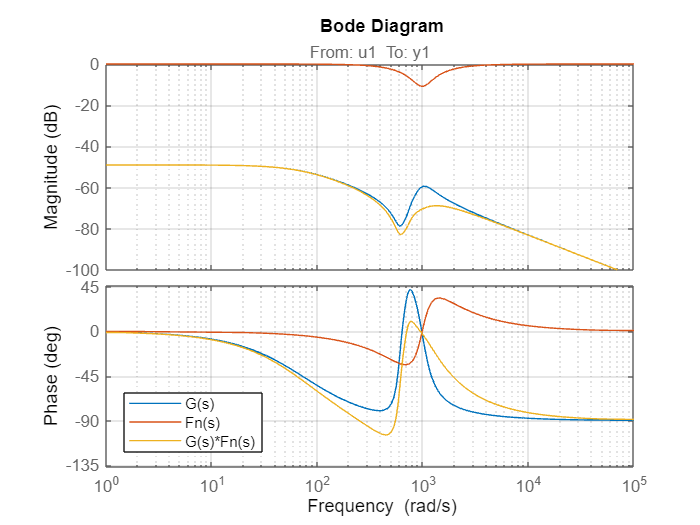

P = G2*notch;
figure
bode(G2)
hold on
bode(notch)
grid on
bode(P)
hold off
legend('G(s)','Fn(s)','G(s)*Fn(s)','Location','best')

Prima di procedere con la taratura si inserisce un filtro passa basso per attenuare le alte frequenze dell'azione di controllo 

Tf2_vel = (1/1000)

Tf2_vel = 1.0000e-03

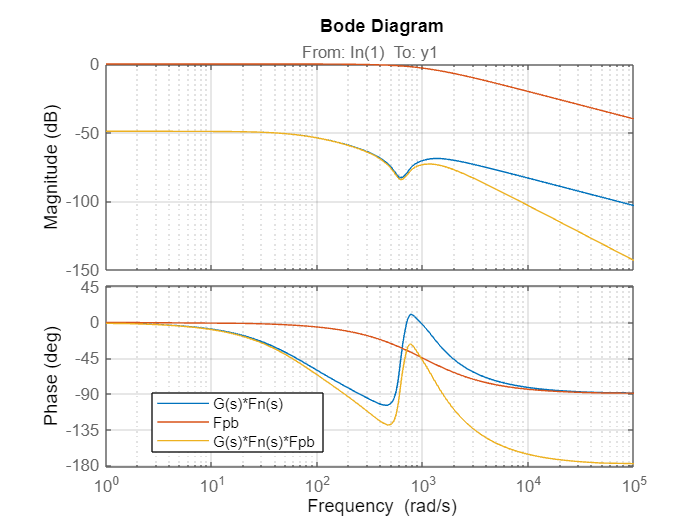

F = 1/(Tf2_vel*s+1);
figure
bode(P)
hold on 
bode(F)
bode(F*P)
legend('G(s)*Fn(s)','Fpb','G(s)*Fn(s)*Fpb','Location','best')
grid on
hold off

P= P*F,

P =
 
  A = 
              x1         x2         x3         x4         x5         x6         x7         x8
   x1     -208.2      722.6     -11.51      152.2     -162.1     -214.6          0      217.4
   x2      -1288     -208.2      95.92     -387.1      419.8      394.2          0     -399.4
   x3    0.08928   -0.03356     -95.25      598.3     -17.25     -22.47          0      22.77
   x4    0.06546    0.09338     -834.3     -95.25      55.45      52.63          0     -53.34
   x5  -0.002188    0.03942    0.01048    0.01462     -73.63      -1999          0       2026
   x6          0          0          0          0          0      -1382       -951       1000
   x7          0          0          0          0          0       1024          0          0
   x8          0          0          0          0          0          0          0      -1000
 
  B = 
       u1
   x1   0
   x2   0
   x3   0
   x4   0
   x5   0
   x6   0
   x7   0
   x8  32
 
  C = 
              x1         x2      

e poi si procede alla scelta dell'omega di taglio in modo da avere che risononza sia attenuata di almeno 6dB 

wc = 320;

Kp2_vel = 1/abs(freqresp(P,wc))

Kp2_vel = 1.8294e+03

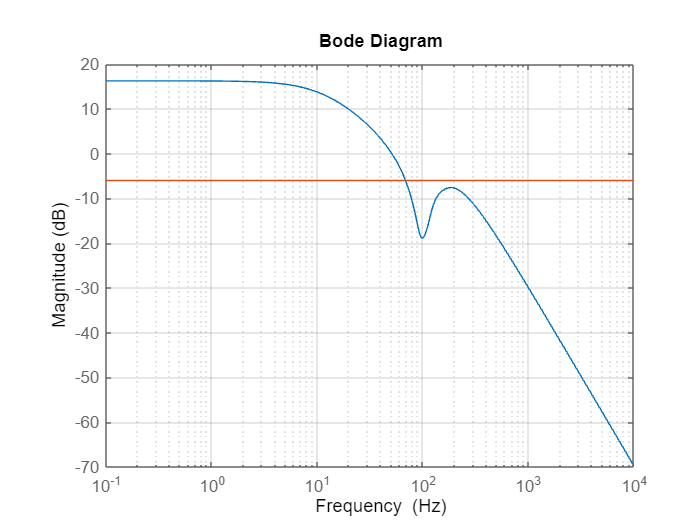



C = Kp2_vel;
L_Int = C*P;
h = bodeplot(L_Int);
setoptions(h,'FreqUnits','Hz','PhaseVisible','off','grid','on');
hold on 
bodeplot(tf(0.5))%valore corrispondente a  -6.0206dB

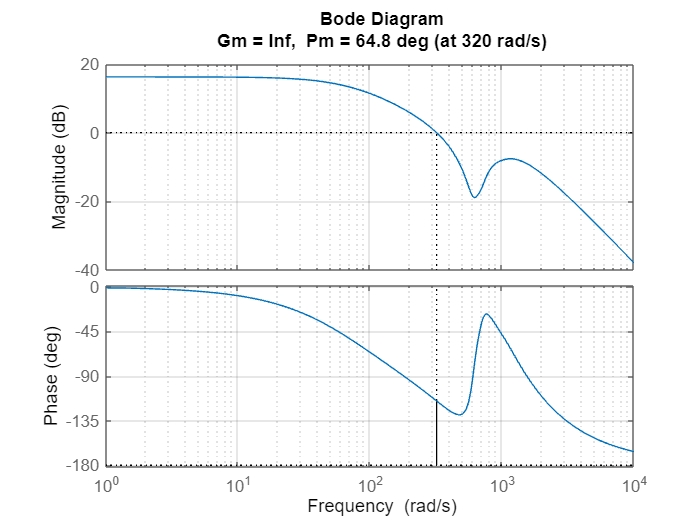



figure
title('Kp*Fn*F*G2')
margin(L_Int)
grid on

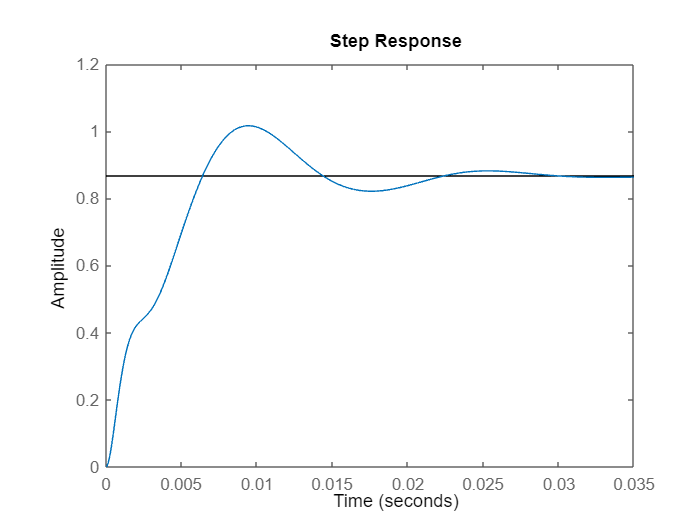


LoopInt = feedback(L_Int,1);
%si esegue uno step del sistema in retroazione solo per sicurezza del
%procedimeneto fatto
figure
step(LoopInt)

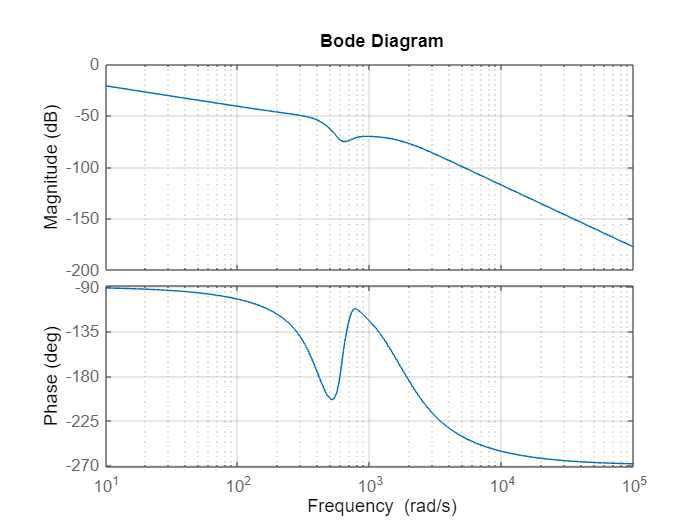

G1 = LoopInt*1/s;
bode(G1)
grid on


wc_des=200;
J=@(x)pivel_cost_function(x,G1,wc_des);
MS=1.6;
wh=2000;
Fh_max=0.1;
wl=0.1;
Dh_max=0.1;%disturbo sul carico ridotto di almeno 10 volte
 
w_vector=logspace(-3,3)'; % [10^-3,10^3]
w_vector=sort([w_vector;wl;wh]);

nlcon=@(x)pivel_constraints(x,G1,w_vector,MS,wh,Fh_max,wl,Dh_max);%anonious function

Risolvo il problema con fmincon, la soluzione è locale.

Impongo che $K_p\in[0.01,10000]$ e $K_i\in[0.01,10000]$

x0=[1,0.1];% scegliere un punto di partenza meglio provarne di diversi
x=fmincon(J,x0,[],[],[],[],[0.001 0.000001],[10000 10000],nlcon)


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x =   175.7173    0.0218


Kp2_pos=x(1)

Kp2_pos = 175.7173

Ki2_pos=x(2)

Ki2_pos = 0.0218

C1=tf([Kp2_pos Ki2_pos],[1 0]);

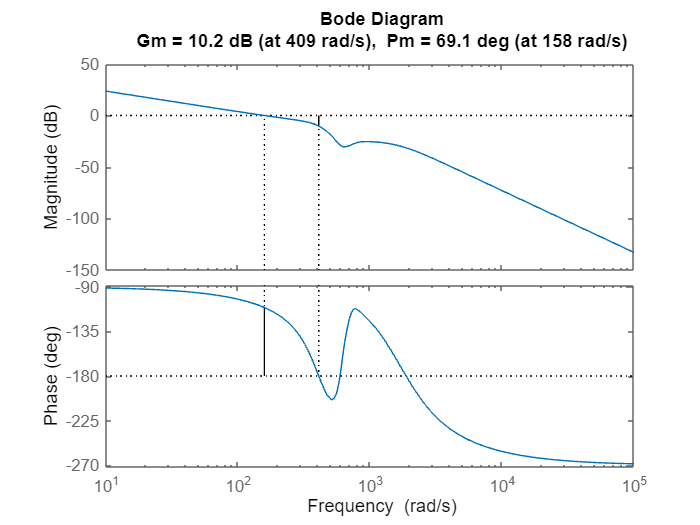

figure
margin(C1*G1)

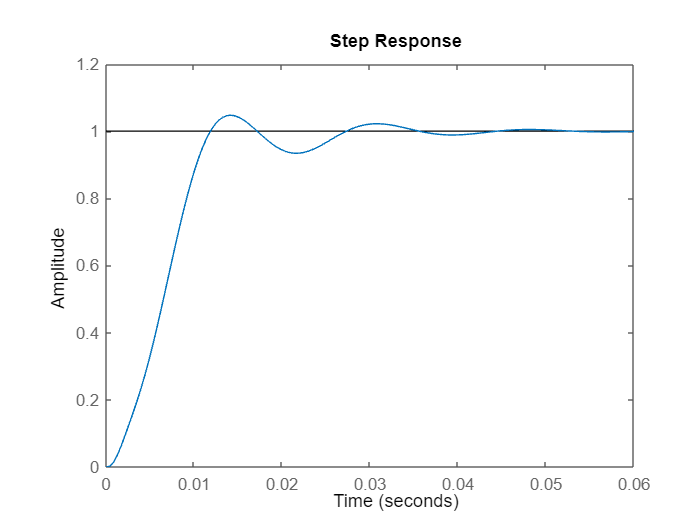


step(feedback(C1*G1,1))

%check della stabilità
C_fr=freqresp(C1*G1,w_vector);
S_fr=1./(1+(C_fr)); % S = 1/(1+L) sensitivity function
max(abs(S_fr))

ans = 1.6000

Sezione di salvataggio dei parametri trovati nella fase di taratura

save("ctrl2.mat","Ki2_pos","Kp2_pos","Kp2_vel","Wn_notch2","xci_p2","xci_z2","Tf2_vel")